## Chapter 3: Modeling in the Time Domain Example Matlab

Consider figure 3.7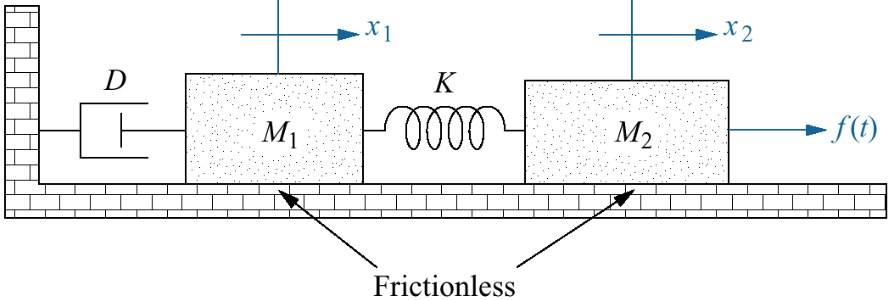

Consider equations of motion starting with motion of $M_1$


$$\left(M_1 s^2+Ds +K\right)X_1(s)=KX_2(s)$$


Taking inverse Laplace:


$$M_1\frac{d^2x_1}{dt^2}+D\frac{dx_1}{dt}+Kx_1=Kx_2$$


or


$$\frac{d^2x_1}{dt^2}=-\frac{K}{M_1}x_1-\frac{D}{M_1}\frac{dx_1}{dt}+\frac{K}{M_1}x_2$$


clear 
syms t x_1(t) x_2(t) K M_1 M_2 D f(t)
eq1=M_1*diff(x_1,2)+D*diff(x_1)+K*x_1==K*x_2

$$eq1(t) = M_{1}\,\frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)+\text{D}\,\frac{\partial }{\partial t}x_{1}\left(t\right)+K\,x_{1}\left(t\right)=K\,x_{2}\left(t\right)$$

eq1=isolate(eq1,diff(x_1,2))

$$eq1 = \frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)=-\frac{\text{D}\,\frac{\partial }{\partial t}x_{1}\left(t\right)+K\,x_{1}\left(t\right)-K\,x_{2}\left(t\right)}{M_{1}}$$

eq1 = collect(eq1,{'x_1','x_2'})

$$eq1 = \frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)=\left(-\frac{K}{M_{1}}\right)\,x_{1}\left(t\right)+\frac{K}{M_{1}}\,x_{2}\left(t\right)-\frac{\text{D}\,\frac{\partial }{\partial t}x_{1}\left(t\right)}{M_{1}}$$

Consider equations of motion starting with motion of $M_2$


$$\left(M_2s^2+K\right)X_2(s)=KX_1(s)+F(s)$$


Taking inverse Laplace:


$$M_2\frac{d^2x_2}{dt^2}+Kx_2=Kx_1+f(t)\\
\mbox{or:}\\
\frac{d^2x_2}{dt^2}=\frac{K}{M_2}x_1-\frac{K}{M_2}x_2+\frac{1}{M_2}f(t)$$


eq2=M_2*diff(x_2(t),2)+K*x_2(t)==K*x_1(t)+f(t)

$$eq2 = M_{2}\,\frac{\partial^{2}}{\partial t^{2}}x_{2}\left(t\right)+K\,x_{2}\left(t\right)=f\left(t\right)+K\,x_{1}\left(t\right)$$

eq2=isolate(eq2,diff(x_2(t),2))

$$eq2 = \frac{\partial^{2}}{\partial t^{2}}x_{2}\left(t\right)=\frac{f\left(t\right)+K\,x_{1}\left(t\right)-K\,x_{2}\left(t\right)}{M_{2}}$$

eq2=collect(eq2,{'x_1', 'x_2'})

$$eq2 = \frac{\partial^{2}}{\partial t^{2}}x_{2}\left(t\right)=\frac{K}{M_{2}}\,x_{1}\left(t\right)+\left(-\frac{K}{M_{2}}\right)\,x_{2}\left(t\right)+\frac{f\left(t\right)}{M_{2}}$$

Let's take our state vector to be:


$$\mathbf{x}=\left[\begin{array}{c}x_1\\\frac{dx_1}{dt}\\x_2\\ \frac{dx_2}{dt}\end{array}\right]$$


x=[x_1; diff(x_1); x_2; diff(x_2)]

$$x(t) = \left(\begin{array}{c} x_{1}\left(t\right)\\ \frac{\partial }{\partial t}x_{1}\left(t\right)\\ x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right) \end{array}\right)$$

Then


$$\frac{d}{dt}\mathbf{x}=\left[\begin{array}{cccc}0&1&0&0\\
-\frac{K}{M_1}&-\frac{D}{M_1}&\frac{K}{M_1}&0\\
0&0&0&1\\
\frac{K}{M_2}&0&-\frac{K}{M_2}&0\end{array}\right]\left[\begin{array}{c}x_1\\\frac{dx_1}{dt}\\x_2\\\frac{dx_2}{dt}\end{array}\right]+\left[\begin{array}{c}0\\0\\0\\\frac{1}{M_2}\end{array}\right]f(t)\\
y(t)=x_2(t)=\left[\begin{array}{cccc}0 &0& 1& 0\end{array}\right]\left[\begin{array}{c}x_1\\\frac{dx_1}{dt}\\x_2\\\frac{dx_2}{dt}\end{array}\right]$$


A=[0 1 0 0;
   -K/M_1 -D/M_1 K/M_1 0
   0 0 0 1;
   K/M_2 0 -K/M_2 0]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{K}{M_{1}} & -\frac{\text{D}}{M_{1}} & \frac{K}{M_{1}} & 0\\ 0 & 0 & 0 & 1\\ \frac{K}{M_{2}} & 0 & -\frac{K}{M_{2}} & 0 \end{array}\right)$$

B=[0; 0; 0; 1/M_2]

$$B = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{1}{M_{2}} \end{array}\right)$$

C=[0 0 1 0]

C =      0     0     1     0


Let's check that we wrote down the matrix correctly

eq3=diff(x,t)==A*x+B*f

$$eq3(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=\frac{\partial }{\partial t}x_{1}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)=\frac{K\,x_{2}\left(t\right)}{M_{1}}-\frac{K\,x_{1}\left(t\right)}{M_{1}}-\frac{\text{D}\,\frac{\partial }{\partial t}x_{1}\left(t\right)}{M_{1}}\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=\frac{\partial }{\partial t}x_{2}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x_{2}\left(t\right)=\frac{f\left(t\right)}{M_{2}}+\frac{K\,x_{1}\left(t\right)}{M_{2}}-\frac{K\,x_{2}\left(t\right)}{M_{2}} \end{array}\right)$$

eq3=collect(eq3,{'x_1', 'x_2'})

$$eq3(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=\frac{\partial }{\partial t}x_{1}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x_{1}\left(t\right)=\left(-\frac{K}{M_{1}}\right)\,x_{1}\left(t\right)+\frac{K}{M_{1}}\,x_{2}\left(t\right)-\frac{\text{D}\,\frac{\partial }{\partial t}x_{1}\left(t\right)}{M_{1}}\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=\frac{\partial }{\partial t}x_{2}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x_{2}\left(t\right)=\frac{K}{M_{2}}\,x_{1}\left(t\right)+\left(-\frac{K}{M_{2}}\right)\,x_{2}\left(t\right)+\frac{f\left(t\right)}{M_{2}} \end{array}\right)$$

rhs(eq3)-[diff(x_1);rhs(eq1);diff(x_2);rhs(eq2)]

$$ans(t) = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

##  Chapter 3: Modeling in the Time Domain

**Transfer Function  to Statespaces**

Going from a transfer function to a state-space representation:

clear
G=tf([1 7 2],[1 9 26 24])

G =
 
       s^2 + 7 s + 2
  -----------------------
  s^3 + 9 s^2 + 26 s + 24
 
Continuous-time transfer function.



[num,den]=tfdata(G,'v')

num =      0     1     7     2


den =      1     9    26    24


[A,B,C,D]=tf2ss(num,den)

A =     -9   -26   -24
     1     0     0
     0     1     0


B =      1
     0
     0


C =      1     7     2


D = 0

This does not look like the Controller (Phase variable) canonical form of the textbook. In this case it is related by a similarity transformation that swaps rows:

T=[0 0 1;0 1 0;1 0 0]

T =      0     0     1
     0     1     0
     1     0     0


A_Nise=T*A*T^-1

A_Nise =      0     1     0
     0     0     1
   -24   -26    -9


B_Nise=T*B

B_Nise =      0
     0
     1


C_Nise = C*T^-1

C_Nise =      2     7     1


You could also build one of the textbook forms directly using matrix operations. For example, to construct the observer canonical form of $G(s)$:

G

G =
 
       s^2 + 7 s + 2
  -----------------------
  s^3 + 9 s^2 + 26 s + 24
 
Continuous-time transfer function.



[num,den]=tfdata(G,'v');
n=length(den)-1

n = 3

A_o=[-den(2:end)' [eye(n-1);zeros(1,n-1)]]

A_o =     -9     1     0
   -26     0     1
   -24     0     0


B_o=num(2:end)'

B_o =      1
     7
     2


C_o=[1 zeros(1,n-1)]

C_o =      1     0     0


Check that we got it right

syms s
collect(C_o*(s*eye(n)-A_o)^-1*B_o)

$$ans = \frac{s^{2}+7\,s+2}{s^{3}+9\,s^{2}+26\,s+24}$$

Alternatively we could use the system objects:

Sys=ss(G)

Sys =
 
  A = 
         x1    x2    x3
   x1    -9  -6.5    -3
   x2     4     0     0
   x3     0     2     0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
 
  C = 
          x1     x2     x3
   y1    0.5  0.875  0.125
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



canSys = canon(Sys, 'companion');
[A,B,C,D]=ssdata(canSys)

A =      0     0   -24
     1     0   -26
     0     1    -9


B =      1
     0
     0


C =      1    -2    -6


D = 0

This is not quite what the Observer Canonical form looks like in the textbook. We can check that it still represents the same transfer function though:

syms s
collect(C*(s*eye(3)-A)^-1*B)

$$ans = \frac{s^{2}+7\,s+2}{s^{3}+9\,s^{2}+26\,s+24}$$

**Statespace to Transfer Function**

Consider the system


$$\mathbf{\dot{x}}=\mathbf{Ax}+\mathbf{B}u\\
\mathbf{\dot{x}}  =  \left[\begin{array} {ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ -24 & -26 & -9   \end{array} \right]\, \mathbf{x}  + \left[\begin{array} {c}0\\ 0 \\ 1 \end{array} \right] \, u     \\
y=\mathbf{Cx}+\mathbf{Du}\\
y  =  [2 \;\;7 \;\;1  ] \, \mathbf{x} +0 u $$


We can get the transfer function as:


$$G(s)=\frac{Y(s)}{U(s)}=\mathbf{C}(s\mathbf{I}-\mathbf{A})^{-1}\mathbf{B}+\mathbf{D}$$


We can define this system and compute the transfer function in Matlab as follows:

A=[0 1 0;0 0 1; -24 -26 -9]

A =      0     1     0
     0     0     1
   -24   -26    -9


B=[0 0 1]'

B =      0
     0
     1


C=[2 7 1]

C =      2     7     1


D=0
[num,den]=ss2tf(A,B,C,D)

num =          0    1.0000    7.0000    2.0000


den =     1.0000    9.0000   26.0000   24.0000


G=tf(num,den)

G =
 
       s^2 + 7 s + 2
  -----------------------
  s^3 + 9 s^2 + 26 s + 24
 
Continuous-time transfer function.



Doing this symbolically!

syms s
G_s=C*(s*eye(3)-A)^-1*B

$$G\_s = \frac{7\,s}{s^{3}+9\,s^{2}+26\,s+24}+\frac{2}{s^{3}+9\,s^{2}+26\,s+24}+\frac{s^{2}}{s^{3}+9\,s^{2}+26\,s+24}$$

G_s=collect(G_s)

$$G\_s = \frac{s^{2}+7\,s+2}{s^{3}+9\,s^{2}+26\,s+24}$$

myDet=det(s*eye(3)-A)

$$myDet = s^{3}+9\,s^{2}+26\,s+24$$

We see that the equation for the eigenvalues of $\mathbf{A}$corresponds to the denominator for the transfer function so the eigenvalues of the statespace representation correspond the the poles of the transfer function!